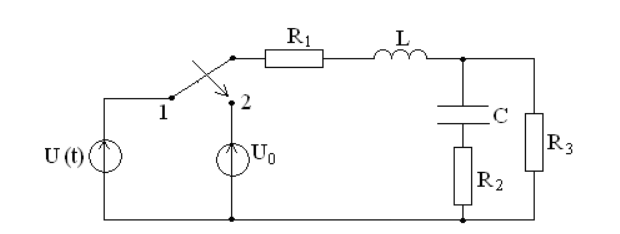

U_m = 140;
fi_0 = 45;
fi = 1500;
U_0 = 50;
L = 25e-3;
C = 8e-6;

R1 = 40;
R2 = 35;
R3 = 250;
U = U_m*cosd(fi_0)+i*U_m*sind(fi_0)

U = 98.9949 + 98.9949i

omeg = 2*pi*fi

omeg = 9.4248e+03

1)

syms IL IC IR
f1 = IL-IC-IR==0;
f2 = IL*R1 + IL*(omeg*L*i)+IR*R3 == U;
f3 = IC*R2+IC*(1/(i*omeg*C))-IR*R3 == 0;
sol = solve(f1,f2,f3);
IC = double(sol.IC)

IC = 0.4710 - 0.2178i

IR = double(sol.IR)

IR = 0.0544 - 0.0555i


IL = imag(double(sol.IL))

IL = -0.2732

UC = imag(IC/(omeg*i*C))

UC = -6.2469

2)

syms ILpr ICpr IRpr ULpr UCpr
f1 = ICpr == 0;
f2 = ULpr == 0;
f3 = R1*ILpr + ULpr + R3*IRpr == U_0;
f4 = ILpr-ICpr-IRpr==0;
f5 = R3*IRpr - UCpr - R2*ICpr==0;
sol = solve(f1,f2,f3,f4,f5);

UCpr = double(sol.UCpr)

UCpr = 43.1034

ILpr = double(sol.ILpr)

ILpr = 0.1724

3)

syms p
f1 = R1+L*p+( ( (C*p)^-1 + R2 )^-1 + R3^-1)^-1==0;
sol = solve( f1 );
p = double(sol)

p = 	1.0e+03 *

  -1.6333 - 1.5556i
  -1.6333 + 1.5556i


alpha = abs(real(p(1)))

alpha = 1.6333e+03

omeg_sv = abs(imag(p(1)))

omeg_sv = 1.5556e+03


tau = 1/alpha

tau = 6.1224e-04

delta_t = 4.6*tau

delta_t = 0.0028


syms IL_0 IC_0 IR_0 UL_0 UC_0
f1 = IL_0 == IL;
f2 = UC_0 == UC;
f3 = IL_0-IC_0-IR_0==0;
f4 = IL_0*R1+UL_0+IR_0*R3==U_0;
f5 = IR_0*R3-UC_0-IC_0*R2==0;
sol = solve(f1,f2,f3,f4,f5);
IL_0 = double(sol.IL_0)

IL_0 = -0.2732

IC_0 = double(sol.IC_0)

IC_0 = -0.2178

IR_0 = double(sol.IR_0)

IR_0 = -0.0555

UL_0 = double(sol.UL_0)

UL_0 = 74.7987

UC_0 = double(sol.UC_0)

UC_0 = -6.2469

4)

syms A psi
UCsv = @(t) A*exp(-alpha*t)*sind(omeg_sv*t+psi);
UC_t = @(t) UCpr+UCsv(t);
f1 = UC_t(0) == UC;
UCsv_diff = @(t) -alpha*A*exp(-alpha*t)*sind(omeg_sv*t+psi)+omeg_sv*A*exp(-alpha*t)*cosd(omeg_sv*t+psi);
f2 = IC_0/C==UCsv_diff(0);
sol = solve(f1,f2);
A = double(sol.A)

A =   -85.0881
   85.0881


psi = double(sol.psi)

psi =    35.4500
 -144.5500


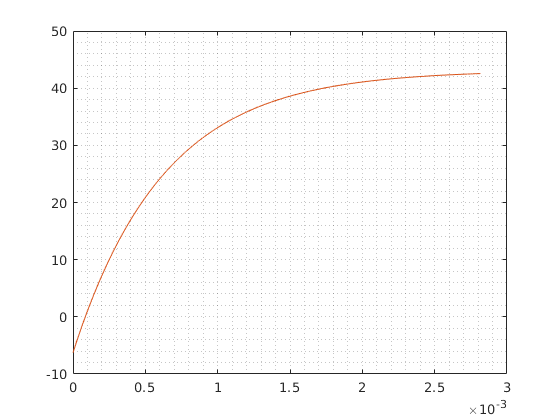


UCsv = @(t) A.*exp(-alpha.*t).*sind(omeg_sv.*t+psi);
UC_t = @(t) UCpr+UCsv(t);
plot(0:1e-6:delta_t,UC_t(0:1e-6:delta_t))
grid minor

Операторный метод

syms p
Delta22 = (det([R1+R3+L*p,U_0/p+IL*L;R3,UC/p]))

$$Delta22 = \frac{279513782196192121\,p-2578151222458103646400}{180143985094819840\,p}$$

Delta = (det([R1+R3+L*p,R3;R3,R2+R3+1/(p*C)]))

$$Delta = \frac{1345874447617848825\,p^{2}+4396523195551639521712\,p+6847431400160985559859200}{188894659314785800\,p}$$

double(solve(Delta))

ans = 	1.0e+03 *

  -1.6333 - 1.5556i
  -1.6333 + 1.5556i
